%% ============================
%  LEITURA E PREPARAÇÃO
% ============================
data = readtable("C:\Users\gabri\Documents\UFMG\TCC\FEMM\lua\resultado\resultados.csv");

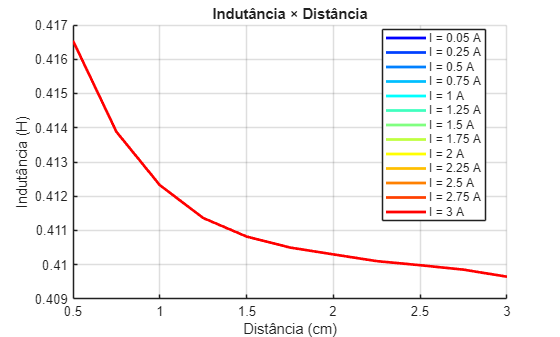


I   = data.Corrente_A_;
d   = -data.Distancia_cm_ / 100; %Distância em metros
L   = data.Indutancia_H_;

% Quero ignorar as distâncias 0,05 e 0,25cm
d_ignorar = [0.0005, 0.0025];
filtro = ~ismember(d, d_ignorar);

% APLICAÇÃO DO FILTRO
I = I(filtro);
d = d(filtro);
L = L(filtro);

% 1. Definir um colormap com 14 cores (por exemplo, usando a função 'jet')
N = length(corrente_unificada); % N = 14
C = jet(N); % 'jet' é um dos colormaps padrão

unique_I = unique(I);

% ============================================
% Gráfico medido - Indutância x distância
% ============================================
figure;
hold on;
grid on;

for k = 1:length(unique_I)
    Ik = unique_I(k);

    % select rows of this current
    mask = (I == Ik);
    
    % sorted by distance
    [d_sorted, idx] = sort(d(mask));
    L_sorted = L(mask);
    L_sorted = L_sorted(idx);

    plot(d_sorted*100, L_sorted, 'Color', C(k,:), 'LineWidth', 2);
end

xlabel('Distância (cm)');
ylabel('Indutância (H)');
title('Indutância × Distância');
legend("I = " + string(unique_I) + " A", 'Location','best');
hold off;



% =====================================================================
% REGRESSÃO PARA ENCONTRAR A EXPRESSÃO DA CURVA (Apenas para a uma corrente)
% =====================================================================

% Corrente selecionada para fazer a regressão (Não faz diferença)
k_corrente = 5; 

Ik = unique_I(k_corrente);

% Seleciona os dados da primeira corrente
ordenador = (I == Ik);
d_corrente = d(ordenador);
L_corrente = L(ordenador);

% Garante que os dados estejam ordenados (necessário para o plot, bom para a regressão)
[d_ordenado, idx] = sort(d_corrente);
L_ordenado = L_corrente(idx);

% Evita a divisão por zero, removendo o ponto em x=0 (se houver)
idx_valido = (d_ordenado ~= 0);
d_final = d_ordenado(idx_valido);
L_final = L_ordenado(idx_valido);

% --- AQUI COMEÇA A REGRESSÃO ---

% Define o índice x^n da regressão
n = 1;

% 1. Linearização: Definir a nova variável X = 1/x^n
X_transformado = 1 ./ (d_final .^ n);

% 2. Regressão Linear: Encontra os coeficientes [k, b] usando polyfit
% polyfit retorna: p(1) = k (coeficiente angular); p(2) = b (intercepto)
p = polyfit(X_transformado, L_final, 1); 

k_fit = p(1); % Coeficiente angular (seu k)
b_fit = p(2); % Intercepto (seu b)

% Erro
L_previsto = (k_fit ./ (d_final .^ n)) + b_fit;
residuos = L_final - L_previsto;
erro = sum(residuos .^ 2)

erro = 1.1621e-07


% 3. Exibir a Expressão Encontrada
fprintf('======================================================\n');

fprintf('  EXPRESSÃO DA CURVA (I = %.2f A):\n', Ik);

  EXPRESSÃO DA CURVA (I = 1.00 A):


fprintf('  L(x) = k/x + b \n');

  L(x) = k/x + b 


fprintf('  Onde: k = %.7f e b = %.7f\n', k_fit, b_fit);

  Onde: k = 0.0000415 e b = 0.4082238


fprintf('  Expressão Final: L(x) = %.7f/x + %.7f\n', k_fit, b_fit);

  Expressão Final: L(x) = 0.0000415/x + 0.4082238


fprintf('  Erro: %.10f', erro);

  Erro: 0.0000001162

fprintf('======================================================\n');

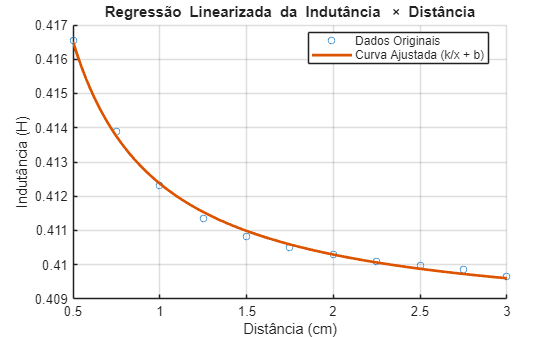


%FAZER O MODELO PARA X² E X³
% Ele tente a indutância do solenoide sozinho


% =====================================================================
% PLOTAGEM E COMPARAÇÃO (Para visualizar o ajuste)
% =====================================================================

figure;
hold on;
grid on;

% Plota os dados originais
plot(d_final*100, L_final, 'o', 'DisplayName', 'Dados Originais', 'MarkerSize', 5);

% Gera a curva de ajuste para comparação
x_plot = linspace(min(d_final), max(d_final), 100);
L_fit_plot = (k_fit ./ x_plot.^n) + b_fit;

% Plota a curva ajustada
plot(x_plot*100, L_fit_plot, '-', 'LineWidth', 2, 'DisplayName', 'Curva Ajustada (k/x + b)');

xlabel('Distância (cm)');
ylabel('Indutância (H)');
title('Regressão Linearizada da Indutância \times Distância');
legend('show', 'Location', 'best');
hold off;